filename = "lessonlearned.csv";
data = readtable(filename,'TextType','string');
textData = data.event_narrative;
textData2 = data.abstract;
labels = data.event_type;
labels2= data.safety;
textData(1:10)

ans = 10×1 string array
    "  Laboratory testing revealed higher than anticipated safety risks from a potential arc-flash event in a manhole environment when conducted at KSCês unreduced fault current levels.¾ The safety risks included bright flash, excessive sound, and smoke.¾¾ Due to these findings and absence of other mitigations installed at the time, manhole entries require full arc-flash PPE.¾ Furthermore, manhole entries were temporarily restricted to short duration inspections until further mitigations could be implemented.¾ With installation of neutral grounding resistors (NGRs) on substation transformers, the flash, sound and flame energy was reduced.¾ The hazard reduction was so substantial that the required PPE would be less cumbersome and enable effective performance of maintenance tasks in the energized configuration.¾  ↵  With the NGR installed, the surge arresters currently used at KSC are not designed for the load and may fail during a fault causing secondary outages 

textData2(1:10)

ans = 10×1 string array
    "  Power system distribution at Kennedy Space Center (KSC) consists primarily of high-voltage, underground cables. These cables include approximately 5000 splices.¾ Splice failures result in arc flash events that are extremely hazardous to personnel in the vicinity of the arc flash. Some construction and maintenance tasks cannot be performed effectively in the required personal protective equipment (PPE), and de-energizing the cables is not feasible due to cost, lost productivity, and safety risk to others implementing the required outages. To verify alternate and effective mitigations, arc flash testing was conducted in a controlled environment. The arc flash effects were greater than expected. Testing also demonstrated the addition of neutral grounding resistors (NGRs) would result in substantial reductions to arc flash effects. As a result, NGRs are being installed on KSC primary substation transformers. The presence of the NGRs, enable usage of less cumb

cleanedDocuments = tokenizedDocument(textData);
cleanedDocuments2 = tokenizedDocument(textData2);
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

    214 tokens: Laboratory testing revealed higher than anticipated safety risks from a potential arc-flash event in a manhole environment when conducted at KSCês unreduced fault current levels . ¾ The safety risks included bright flash , excessive sound , and smoke . ¾ ¾ Due to these findings and absence of other mitigations installed at the time , manhole entries require full arc-flash PPE . ¾ Furthermore , manhole entries were temporarily restricted to short duration inspections until further mitigations could be implemented . ¾ With installation of neutral grounding resistors ( NGRs ) on substation transformers , the flash , sound and flame energy was reduced . ¾ The hazard reduction was so substantial that the required PPE would be less cumbersome and enable effective performance of maintenance tasks in the energized configuration . ¾ With the NGR installed , the surge arrest

cleanedDocuments2(1:10)

ans =   10×1 tokenizedDocument:

    167 tokens: Power system distribution at Kennedy Space Center ( KSC ) consists primarily of high-voltage , underground cables . These cables include approximately 5000 splices . ¾ Splice failures result in arc flash events that are extremely hazardous to personnel in the vicinity of the arc flash . Some construction and maintenance tasks cannot be performed effectively in the required personal protective equipment ( PPE ) , and de-energizing the cables is not feasible due to cost , lost productivity , and safety risk to others implementing the required outages . To verify alternate and effective mitigations , arc flash testing was conducted in a controlled environment . The arc flash effects were greater than expected . Testing also demonstrated the addition of neutral grounding resistors ( NGRs ) would result in substantial reductions to arc flash effects . As a result , NGRs

cleanedDocuments = addPartOfSpeechDetails(cleanedDocuments);
cleanedDocuments = normalizeWords(cleanedDocuments,'Style','lemma');
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

    214 tokens: laboratory testing reveal high than anticipate safety risk from a potential arc-flash event in a manhole environment when conduct at kscês unreduced fault current level . ¾ the safety risk include bright flash , excessive sound , and smoke . ¾ ¾ due to these finding and absence of other mitigation install at the time , manhole entry require full arc-flash ppe . ¾ furthermore , manhole entry be temporarily restrict to short duration inspection until further mitigation can be implement . ¾ with installation of neutral grounding resistor ( ngrs ) on substation transformer , the flash , sound and flame energy be reduce . ¾ the hazard reduction be so substantial that the require ppe would be less cumbersome and enable effective performance of maintenance task in the energized configuration . ¾ with the ngr install , the surge arrester currently use at ksc be not design 

cleanedDocuments2 = addPartOfSpeechDetails(cleanedDocuments2);
cleanedDocuments2 = normalizeWords(cleanedDocuments2,'Style','lemma');
cleanedDocuments2(1:10)

ans =   10×1 tokenizedDocument:

    168 tokens: power system distribution at kennedy space center ( ksc ) consist primarily of high-voltage , underground cable . these cable include approximately 5000 splice . ¾ splice failure result in arc flash event that be extremely hazardous to personnel in the vicinity of the arc flash . some construction and maintenance task can not be perform effectively in the require personal protective equipment ( ppe ) , and de-energize the cable be not feasible due to cost , lose productivity , and safety risk to others implement the require outage . to verify alternate and effective mitigation , arc flash testing be conduct in a controlled environment . the arc flash effect be great than expect . testing also demonstrate the addition of neutral grounding resistor ( ngrs ) would result in substantial reduction to arc flash effect . as a result , ngrs be be install on ksc primary sub

cleanedDocuments = erasePunctuation(cleanedDocuments);
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

    195 tokens: laboratory testing reveal high than anticipate safety risk from a potential arcflash event in a manhole environment when conduct at kscês unreduced fault current level ¾ the safety risk include bright flash excessive sound and smoke ¾ ¾ due to these finding and absence of other mitigation install at the time manhole entry require full arcflash ppe ¾ furthermore manhole entry be temporarily restrict to short duration inspection until further mitigation can be implement ¾ with installation of neutral grounding resistor ngrs on substation transformer the flash sound and flame energy be reduce ¾ the hazard reduction be so substantial that the require ppe would be less cumbersome and enable effective performance of maintenance task in the energized configuration ¾ with the ngr install the surge arrester currently use at ksc be not design for the load and may fail during

cleanedDocuments2 = erasePunctuation(cleanedDocuments2);
cleanedDocuments2(1:10)

ans =   10×1 tokenizedDocument:

    147 tokens: power system distribution at kennedy space center ksc consist primarily of highvoltage underground cable these cable include approximately 5000 splice ¾ splice failure result in arc flash event that be extremely hazardous to personnel in the vicinity of the arc flash some construction and maintenance task can not be perform effectively in the require personal protective equipment ppe and deenergize the cable be not feasible due to cost lose productivity and safety risk to others implement the require outage to verify alternate and effective mitigation arc flash testing be conduct in a controlled environment the arc flash effect be great than expect testing also demonstrate the addition of neutral grounding resistor ngrs would result in substantial reduction to arc flash effect as a result ngrs be be install on ksc primary substation transformer the presence of the 

cleanedDocuments = removeStopWords(cleanedDocuments);
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

    122 tokens: laboratory testing reveal high anticipate safety risk potential arcflash event manhole environment conduct kscês unreduced fault current level ¾ safety risk include bright flash excessive sound smoke ¾ ¾ due finding absence mitigation install time manhole entry require full arcflash ppe ¾ furthermore manhole entry temporarily restrict short duration inspection further mitigation implement ¾ installation neutral grounding resistor ngrs substation transformer flash sound flame energy reduce ¾ hazard reduction substantial require ppe less cumbersome enable effective performance maintenance task energized configuration ¾ ngr install surge arrester currently ksc design load fail fault cause secondary outage increase repair time ¾ replacement surge arrester conduct 23 year due result hundred facility outage impact surge suppressor upgraded ngrs manhole construction maint

cleanedDocuments2 = removeStopWords(cleanedDocuments2);
cleanedDocuments2(1:10)

ans =   10×1 tokenizedDocument:

    96 tokens: power system distribution kennedy space center ksc consist primarily highvoltage underground cable cable include approximately 5000 splice ¾ splice failure result arc flash event extremely hazardous personnel vicinity arc flash construction maintenance task perform effectively require personal protective equipment ppe deenergize cable feasible due cost lose productivity safety risk others implement require outage verify alternate effective mitigation arc flash testing conduct controlled environment arc flash effect great expect testing demonstrate addition neutral grounding resistor ngrs result substantial reduction arc flash effect result ngrs install ksc primary substation transformer presence ngrs enable usage less cumbersome ppe increase
    33 tokens: sampling analysis process verify cleanliness gas liquid load payload related ground support equipment gse intro

cleanedDocuments = removeShortWords(cleanedDocuments,2);
cleanedDocuments = removeLongWords(cleanedDocuments,15);
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

    113 tokens: laboratory testing reveal high anticipate safety risk potential arcflash event manhole environment conduct kscês unreduced fault current level safety risk include bright flash excessive sound smoke due finding absence mitigation install time manhole entry require full arcflash ppe furthermore manhole entry temporarily restrict short duration inspection further mitigation implement installation neutral grounding resistor ngrs substation transformer flash sound flame energy reduce hazard reduction substantial require ppe less cumbersome enable effective performance maintenance task energized configuration ngr install surge arrester currently ksc design load fail fault cause secondary outage increase repair time replacement surge arrester conduct year due result hundred facility outage impact surge suppressor upgraded ngrs manhole construction maintenance operation ap

cleanedDocuments2 = removeShortWords(cleanedDocuments2,2);
cleanedDocuments2 = removeLongWords(cleanedDocuments2,15);
cleanedDocuments2(1:10)

ans =   10×1 tokenizedDocument:

    95 tokens: power system distribution kennedy space center ksc consist primarily highvoltage underground cable cable include approximately 5000 splice splice failure result arc flash event extremely hazardous personnel vicinity arc flash construction maintenance task perform effectively require personal protective equipment ppe deenergize cable feasible due cost lose productivity safety risk others implement require outage verify alternate effective mitigation arc flash testing conduct controlled environment arc flash effect great expect testing demonstrate addition neutral grounding resistor ngrs result substantial reduction arc flash effect result ngrs install ksc primary substation transformer presence ngrs enable usage less cumbersome ppe increase
    33 tokens: sampling analysis process verify cleanliness gas liquid load payload related ground support equipment gse introdu

cleanedBag = bagOfWords(cleanedDocuments)

cleanedBag =   bagOfWords with properties:

          Counts: [1637×7764 double]
      Vocabulary: [1×7764 string]
        NumWords: 7764
    NumDocuments: 1637


tbl = topkwords(cleanedBag,10)

tbl = 10×2 table
        Word         Count
    _____________    _____

    "system"          911 
    "design"          637 
    "project"         629 
    "test"            622 
    "flight"          500 
    "requirement"     495 
    "result"          442 
    "program"         433 
    "failure"         414 
    "process"         411 


cleanedBag2 = bagOfWords(cleanedDocuments2)

cleanedBag2 =   bagOfWords with properties:

          Counts: [1637×5478 double]
      Vocabulary: [1×5478 string]
        NumWords: 5478
    NumDocuments: 1637


cleanedBag = removeInfrequentWords(cleanedBag,2)

cleanedBag =   bagOfWords with properties:

          Counts: [1637×3443 double]
      Vocabulary: [1×3443 string]
        NumWords: 3443
    NumDocuments: 1637


cleanedBag2 = removeInfrequentWords(cleanedBag2,2)

cleanedBag2 =   bagOfWords with properties:

          Counts: [1637×2418 double]
      Vocabulary: [1×2418 string]
        NumWords: 2418
    NumDocuments: 1637


[cleanedBag,idx] = removeEmptyDocuments(cleanedBag);
labels(idx) = [];
cleanedBag

cleanedBag =   bagOfWords with properties:

          Counts: [1637×3443 double]
      Vocabulary: [1×3443 string]
        NumWords: 3443
    NumDocuments: 1637


[cleanedBag2,idx] = removeEmptyDocuments(cleanedBag2);
labels(idx) = [];
cleanedBag2

cleanedBag2 =   bagOfWords with properties:

          Counts: [868×2418 double]
      Vocabulary: [1×2418 string]
        NumWords: 2418
    NumDocuments: 868


newText = "NASA is better served by including certain baseline information, data, and (at least temporary) access to the model (or model-system) as required deliverables for analysis contracts. This additional information, data, or products can provide a more concrete basis for understanding the model, its development, and use.";
newDocuments = preprocessLessonLearned(newText)

newDocuments =   tokenizedDocument:

   27 tokens: nasa well serve include certain baseline information datum least temporary access model modelsystem require deliverable analysis contract additional information datum product provide concrete basis understand model development


rawDocuments = tokenizedDocument(textData);
rawBag = bagOfWords(rawDocuments)

rawBag =   bagOfWords with properties:

          Counts: [1637×12190 double]
      Vocabulary: [1×12190 string]
        NumWords: 12190
    NumDocuments: 1637


rawDocuments2 = tokenizedDocument(textData2);
rawBag2 = bagOfWords(rawDocuments2)

rawBag2 =   bagOfWords with properties:

          Counts: [1637×8382 double]
      Vocabulary: [1×8382 string]
        NumWords: 8382
    NumDocuments: 1637


numWordsCleaned = cleanedBag.NumWords;
numWordsRaw = rawBag.NumWords;
reduction = 1 - numWordsCleaned/numWordsRaw

reduction = 0.7176

numWordsCleaned2 = cleanedBag2.NumWords;
numWordsRaw2 = rawBag2.NumWords;
reduction2 = 1 - numWordsCleaned2/numWordsRaw2

reduction2 = 0.7115

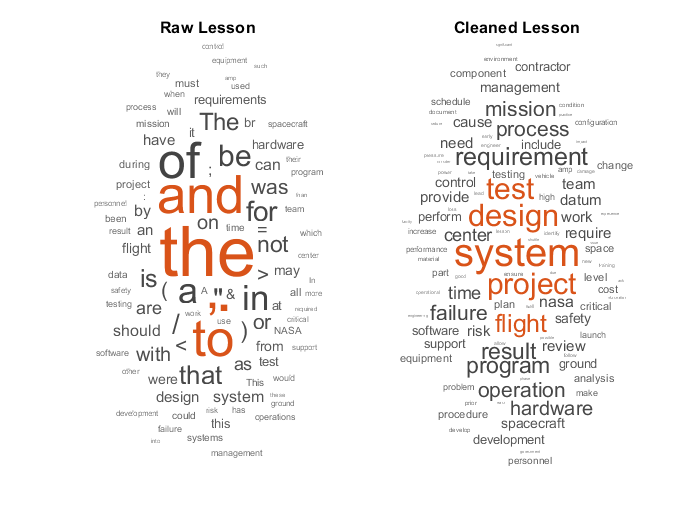

figure
subplot(1,2,1)
wordcloud(rawBag);
title("Raw Lesson")
subplot(1,2,2)
wordcloud(cleanedBag);
title("Cleaned Lesson")

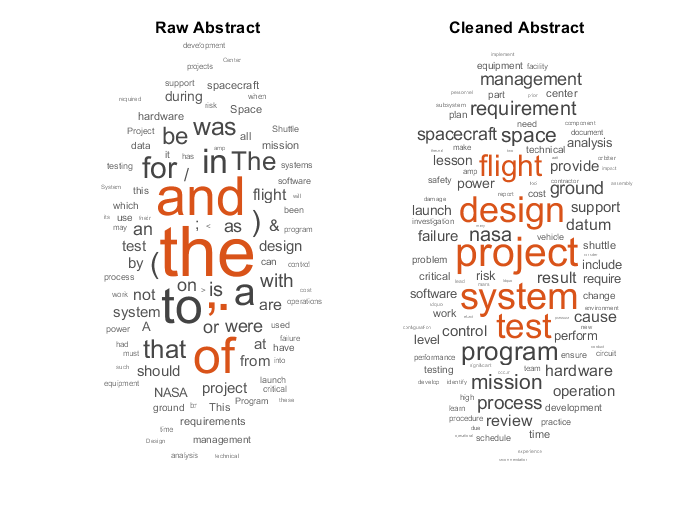

figure
subplot(1,2,1)
wordcloud(rawBag2);
title("Raw Abstract")
subplot(1,2,2)
wordcloud(cleanedBag2);
title("Cleaned Abstract")

function documents = preprocessLessonLearned(textData)
documents = tokenizedDocument(textData);
documents = addPartOfSpeechDetails(documents);
documents = normalizeWords(documents,'Style','lemma');
documents = erasePunctuation(documents);
documents = removeStopWords(documents);
documents = removeShortWords(documents,2);
documents = removeLongWords(documents,15);
end